# Structural Balance in Polymicrobial Networks

*[This document is a MATLAB live script originally executed on version R2017b (9.3.0.713579).]*

clear; % Reset the MATLAB workspace for consistency
GraphDefaults();

## Analysis

Datasets = LoadDatasets();
SummarizeDatasets(Datasets);

| Data set        | Nodes | Edges |  <k>  |  p(+)  | Summary                          |
|:----------------|------:|------:|------:|-------:|:---------------------------------|
| [Brown]         |   10  |   88  |  8.8  | +0.45  | Cystic Fibrosis lung microbiome  |
| [Friedman]      |    8  |   53  |  6.6  | +0.74  | Synthetic soil microbiome        |
| [Lo]            |   15  |   35  |  2.3  | +0.40  | Human gut microbiome             |
| [Xiao]          |    7  |   41  |  5.9  | +0.68  | Synthetic maize root microbiome  |


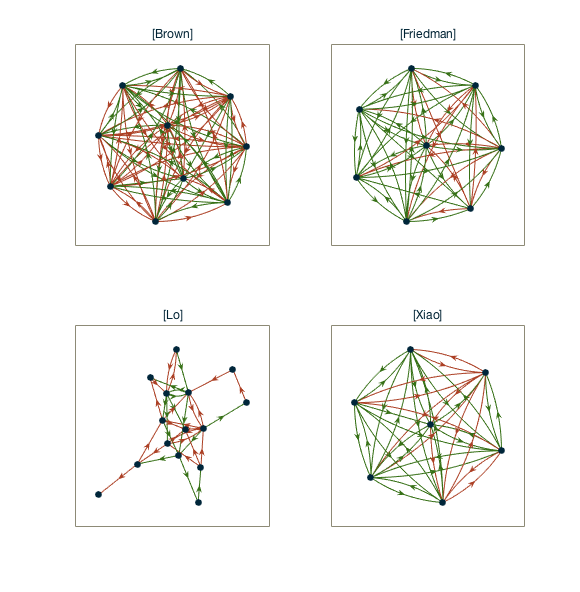

GraphDatasets(Datasets);

Only consider networks with average degree greater than 2.

Valid = arrayfun(@(dataset) numedges(dataset.graph)/numnodes(dataset.graph) > 2, Datasets);

Evaluate structural balance using cycle index from [Wasserman1994] compared to graphs with topology-preserving random signed graphs. Data for both traditional structural balance and *weak structure balance* as proposed by [Davis1967]

RandomTrials = LoadRandomTrials(Datasets);
CycleIndexRandom(Datasets(Valid), RandomTrials(Valid,:,:));

| Data set        |  ci  |  ci` | std` | ci_w | ci_w`| std` |
|:----------------|-----:|-----:|-----:|-----:|-----:|-----:|
| [Brown]         | 0.50 | 0.50 | 0.03 | 0.70 | 0.66 | 0.05 |
| [Friedman]      | 0.48 | 0.55 | 0.06 | 0.48 | 0.57 | 0.06 |
| [Lo]            | 0.17 | 0.50 | 0.20 | 0.33 | 0.71 | 0.20 |
| [Xiao]          | 0.65 | 0.52 | 0.07 | 0.66 | 0.56 | 0.06 |


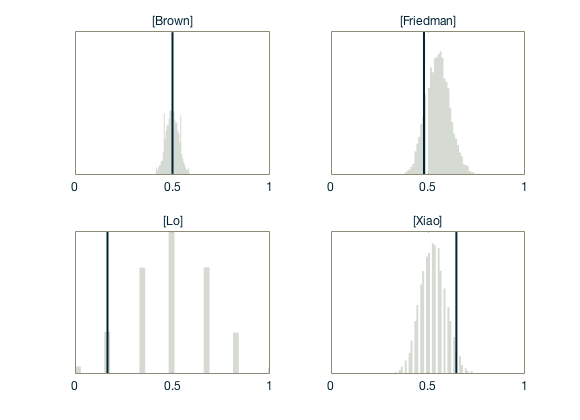

GraphRandom(Datasets(Valid), RandomTrials(Valid,:,:), false);

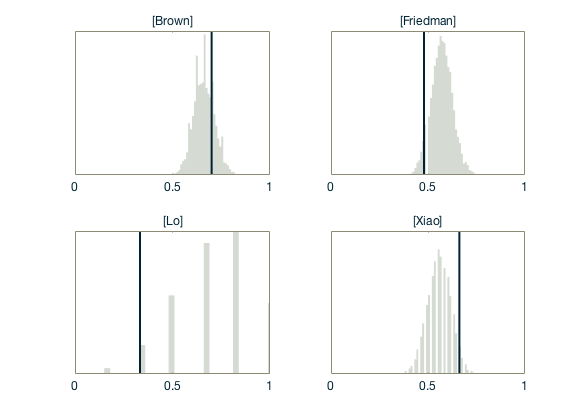

GraphRandom(Datasets(Valid), RandomTrials(Valid,:,:), true)

Using multiple cycle lengths.

CycleIndex(Datasets(Valid), false)

| Data set        |  k=2  |  k=3  |  k=4  |  k=5  |  k=6  |  k=7  |
|:----------------|------:|------:|------:|------:|------:|------:|
| [Brown]         |  0.53 |  0.50 |  0.49 |  0.52 |  0.49 |  0.51 |
| [Friedman]      |  0.48 |  0.48 |  0.45 |  0.45 |  0.47 |  0.50 |
| [Lo]            |  1.00 |  0.17 |  0.67 |  0.55 |  0.22 |  0.82 |
| [Xiao]          |  0.85 |  0.65 |  0.52 |  0.46 |  0.43 |  0.44 |


Using weak structure balance.

CycleIndex(Datasets(Valid), true)

| Data set        |  k=2  |  k=3  |  k=4  |  k=5  |  k=6  |  k=7  |
|:----------------|------:|------:|------:|------:|------:|------:|
| [Brown]         |  0.53 |  0.70 |  0.77 |  0.88 |  0.94 |  0.97 |
| [Friedman]      |  0.48 |  0.48 |  0.48 |  0.52 |  0.61 |  0.70 |
| [Lo]            |  1.00 |  0.33 |  0.83 |  1.00 |  1.00 |  1.00 |
| [Xiao]          |  0.85 |  0.66 |  0.61 |  0.63 |  0.69 |  0.77 |


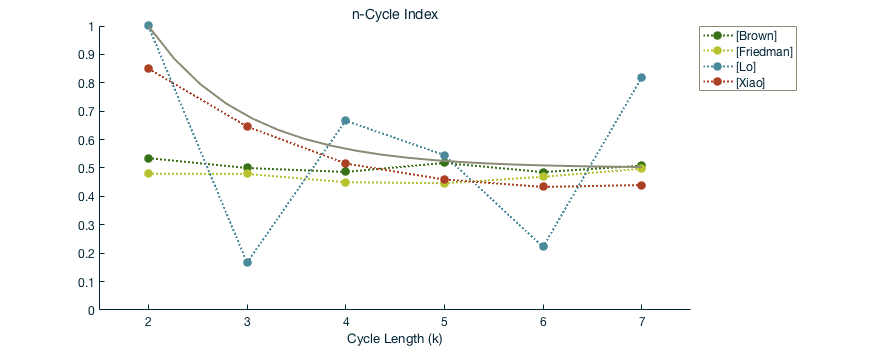

GraphCycleIndex(Datasets(Valid))

Evaluate structural balance using signed clustering coefficent from [Kunegis2014].

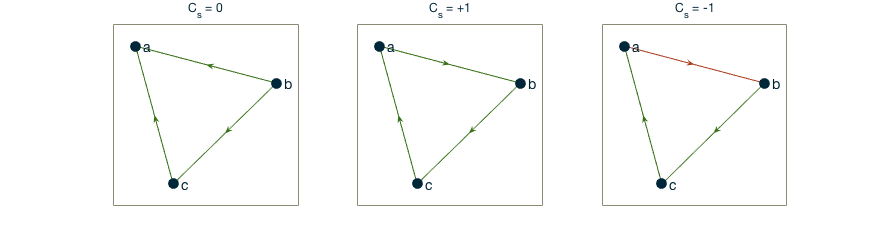

GraphClusteringCoefficient()

ClusteringCoefficient(Datasets(Valid))

| Data set        |  c   |  c_s  |   S   |
|:----------------|-----:|------:|------:|
| [Brown]         | 0.93 | +0.00 | +0.00 |
| [Friedman]      | 0.87 | -0.04 | -0.04 |
| [Lo]            | 0.08 | -0.05 | -0.67 |
| [Xiao]          | 0.93 | +0.27 | +0.29 |


## References

[Bucci2016] Bucci V et al. (2016) MDSINE: Microbial Dynamical Systems INference Engine for microbiome time-series analyses. *Genome biology* 17:121.

[Davis1967] Davis JA (1967) Clustering and structural balance in graphs. *Human relations* 20:181–187.

[Friedman2017] Friedman J, Higgins LM, Gore J (2017) Community structure follows simple assembly rules in microbial microcosms. *Nature Ecology & Evolution*:0109.

[Kunegis2014] Kunegis J (2014) Applications of structural balance in signed social networks. Preprint arXiv:1402.6865 K.

[Lo2017] Lo C, Marculescu R (2017) Inferring Microbial Interactions from Metagenomic Time-series Using Prior Biological Knowledge. *Proceedings of the 8th ACM International Conference on Bioinformatics, Computational Biology,and Health Informatics*:168–177.

[deVos2017] de Vos MGJ, Zagorski M, McNally A, Bollenbach T (2017) Interaction networks, ecological stability, and collective antibiotic tolerance in polymicrobial infections. *Proceedings of the National Academy of Sciences* 114:10666–10671.

[Wasserman1994] Wasserman S, Faust K (1994) *Social network analysis: Methods and applications* (Cambridge university press).

[Xiao2017] Xiao Y, Angulo M, Friedman J, Waldor M, bioRxiv W-S (2017) Mapping the ecological networks of microbial communities from steady-state data. *bioRxiv*.

## Supplementary Information

*Data Sets*

% DetailDatasets(Datasets)

*Code*

function Datasets = LoadDatasets()
% Loads datasets for analysis

    if exist('sbalance_datasets2.mat', 'file') == 2
        % If a cached copy of the data sets exists, retrieve it. Otherwise, calculating
        % the structural balance information from scratch can be computationally intensive.
        % To force a recalculation, delete (or rename) the cached file.
        load('sbalance_datasets2.mat', 'Datasets');
    else
        Datasets = struct(...
            'ref',  {'[Brown]','[Friedman]','[Lo]','[Xiao]'}, ...
            'file', {'brown','friedman2017','lo2017','xiao2017'}, ...
            'summary', { ...
                'Cystic Fibrosis lung microbiome', ...
                'Synthetic soil microbiome', ...
                'Human gut microbiome', ...
                'Synthetic maize root microbiome', ...
            }, ...
            'details', { ...
                'Interaction matrix computed by MDSINE toolset from time-series data of common taxa found in lung microbiome of Cystic Fibrosis patients. Data from Brown Lab at Georgia Tech School of BioSciences; not yet published.', ...
                'Interaction matrix derived from pair-wise competition experiments between common soil-dwelling taxa. Data from Table S3 of [Friedman2017].', ...
                'Interaction matrix computed using linear regression and co-occurrence of time series data from human gut microbiome. Data from Figure 10a of [Lo2017].', ...
                'Interaction matrix calculated from steady-state measurement of relative abundance of maize root taxa over multiple trials. Data from Figure 6a of [Xiao2017].'
            } ...
        );
        for i=1:size(Datasets,2)
            %Datasets(i).data = dlmread([Datasets(i).file '.csv'], ',');
            Datasets(i).data = readtable([Datasets(i).file '.csv']);
            % Convert raw data to signed adjacency matrix (-1, 0, 1) with diagonal elements of 0.
            Datasets(i).adj = sign(table2array(Datasets(i).data));
            Datasets(i).adj(logical(eye(size(Datasets(i).adj)))) = 0;
            % Compute structural balance information
            Datasets(i).sbdata = StructuralBalance(Datasets(i).adj);
            % Create graph structure
            Datasets(i).graph = digraph(Datasets(i).adj,'OmitSelfLoops');
        end
        
        % Having calculated the data, save a cached copy.
        save('sbalance_datasets2.mat', 'Datasets');
    end
end

function s = StructuralBalance(A, MaxCycleLength)
% Computes structural balance data for a network
% defined by adjancency matrix A. The return value
% s is a matrix with n rows and 4 columns, where
% n is the number of nodes in the network (i.e.
% the dimension of A). For each row:
%
%     s(i,1) : number of balanced cycles
%     s(i,2) : number of unbalanced cycles
%     s(i,3) : number of incomplete cycles
%     s(i,4) : number of weakly balanced cycles
%     s(i,5) : number of (i-1)-paths
%     s(i,6) : number of (i-1)-directed paths
%
% For i > 1, the row corresponds solely to cycles
% of length i. The first row (i=1) corresponds
% to total cycles of all lengths.
%
% The optional parameter maxCycleLength speficies
% the largest cycle to consider. Values greater than
% 10 can require substantial computational resources.

    A = sign(A);
    n = size(A, 1);
    
    % If the maxCycles parameter was not supplied,
    % default it to the minimum of
    %
    %  - the size of the adjacency matrix
    %  - a practical value for desktop computers

    if ~exist('MaxCycleLength','var') || isempty(MaxCycleLength)
        MaxCycleLength = min(n, 7);
    end

    s = zeros(MaxCycleLength, 6);

    % Consider each possible value of cycle length, k

    for k = 2:MaxCycleLength

        % Circular permutations of n items k at at time
        % define the cycles. There will be P(n,k)/k total,
        % where P(n,k) is the number of traditional 
        % (not circular) permutations. This number is
        % efficiently calculated as
        %
        %     prod(n-k+1:n)/k
        %
        % To generate these permutations, pick a maximum
        % index for a cycle, maxItem. This index has
        % to be at least k (since the cycle has k nodes)
        % and it can range as high as n.

        for maxItem=k:n
            
            % After picking the maximum index in the
            % the cycle, consider all possible _unique_
            % permutations of k-1 items from maxItem-1
            % choices. Appending maxItem to those permutations
            % gives us the cyclic permutations.
            %
            % Picking k-1 items and then adding maxItem gives
            % a length of k, and picking from up to maxItem-1
            % ensures that maxItem is the maximum valued item.
            % Because each cycle starts with a unique
            % permutation, each cycle is guaranteed to
            % be unique. And because each cycle has the
            % same value maxItem in the final position, none
            % can be circular shifts of each other.
            %
            % Because the iteration of maxItem ranges from its
            % minimum to its maximum possible values, the
            % result is all possible cycles.
            %
            % The following code can show the algorithm in
            % action (e.g. for debugging). The implementation
            % does not actually generate the permutations,
            % though, as that's quite memory-intensive.
            % Typical computers run out of memory if n > 10.
            %
            %     p = perms(1:maxItem-1);
            %     p = unique(p(:,1:k-1),'rows');
            %     cycles = [p, repmat(i, size(p,1), 1)];
            %     if maxItem==k disp([num2str(k), '-cycles:']), end
            %     disp(cycles)
            %
            % Since we can't afford the memory of accumulating
            % all the possible permutations, we generate them
            % one at a time, calculate the resulting cycle
            % product from the adjacency matrix, and then go
            % to the next permutation. The algorithm for
            % generating permutations is adapted from Alistair
            % Israel.
            
            % Use a vector to keep track of all possible
            % items from which to choose. The algorithm
            % rearranges this vector to reveal the possible
            % permutations.
            
            items = 1:maxItem-1;

            while true

                % At each iteration, the cycle is the
                % concatenation of three components:
                %
                %  - the first k-1th elements in the vector
                %    (i.e. the linear permutation)
                %  - the element i (the maximum index)
                %  - the first element (to close the cycle)

                cycle = [items(1:k-1), maxItem, items(1)];
                
                % Multiply the weights of the edges corresponding
                % to the cycle. If the result is positive, then
                % there is an even number of negative weights.
                % If negative, there is an odd number. And if the
                % result is zero, then one of the weights is zero,
                % and the cycle doesn't actually exist on the
                % network.
                
                path = diag(A(cycle(1:end-1), cycle(2:end)));
                balance = prod(path);

                % disp([num2str(k), '-cycle: ', num2str(cycle), ', d = ', num2str(balance)])

                if balance > 0
                    s(k,1) = s(k,1) + 1;
                    s(k,4) = s(k,4) + 1;
                elseif balance < 0
                    s(k,2) = s(k,2) + 1;
                    if sum(path) ~= k - 2
                      s(k,4) = s(k,4) + 1;
                    end
                else
                    s(k,3) = s(k,3) + 1;
                end
 
                if sum(abs(path)) == k-1
                    s(k,5) = s(k,5) + 1;
                end
                
                % The rest of the loop code calculates the next
                % permutation.

                % The items vector contains a full set of n elements,
                % but we only want to pick k from that set. Consider
                % the kth element in the vector to be the edge.
        
                % Look for the first ascent to the right of the edge.
                % In this case a right ascent is the first element whose
                % value is greater than the edge element.

                rightAscent = k - 1 + find(items(k:end) > items(k-1), 1, 'first');
        
                % If we found a right ascent, then swap that element
                % with the edge element and continue to the next
                % iteration in the algorithm.

                if ~isempty(rightAscent)
                    [items(k-1), items(rightAscent)] = deal(items(rightAscent), items(k-1));
                    continue;
                end

                % Reverse items after the edge.

                items = [items(1:k-1), fliplr(items(k:end))];

                % Since we didn't find a right ascent, look for a left
                % ascent. A left ascent is the first element (moving
                % to the left) whose value is less than its neighbor
                % to the right.

                leftAscent = find((items(1:k-2) - items(2:k-1)) < 0, 1, 'last');
        
                % If there was no left ascent, then the entire vector
                % of items is in descending order, and we're done.

                if isempty(leftAscent) 
                    break;
                end

                % Now look again for a right ascent. In this case the
                % right ascent is the first item whose value is larger
                % than the left ascent.

                rightAscent = leftAscent + find(items(leftAscent+1:end) > items(leftAscent), 1, 'last');

                % Swap the left and right ascents.

                [items(leftAscent), items(rightAscent)] = deal(items(rightAscent), items(leftAscent));

                % Reverse items after the left ascent.

                items = [items(1:leftAscent), fliplr(items(leftAscent+1:end))];

            end
        end
    end
    
    % Now that we have counts for all of the individual
    % cycle lengths, the final step is to fill in the
    % summation.

    s(1,:) = sum(s,1);

end

function SummarizeDatasets(Datasets)
    fprintf('| Data set        | Nodes | Edges |  <k>  |  p(+)  | Summary                          |\n');
    fprintf('|:----------------|------:|------:|------:|-------:|:---------------------------------|\n');
    for i=1:length(Datasets)
        fprintf('| %-15s |   %2d  |  %3d  |  %3.1f  | %+3.2f  | %-32s |\n', ...
            Datasets(i).ref, ...
            numnodes(Datasets(i).graph), ...
            numedges(Datasets(i).graph), ...
            numedges(Datasets(i).graph) / numnodes(Datasets(i).graph), ...
            sum(sum(Datasets(i).adj == 1)) / (sum(sum(Datasets(i).adj == 1)) + sum(sum(Datasets(i).adj == -1))), ...
            Datasets(i).summary ...
        );
    end
end

function randomTrials = LoadRandomTrials(Datasets)
% Loads random trial data

    if exist('sbalance_trials2.mat', 'file') == 2
        % If a cached copy of the data sets exists, retrieve it.
        % To force a recalculation, delete (or rename) the cached file.
        load('sbalance_trials2.mat', 'randomTrials');
    else
        numTrials = 10000;
        randomTrials = zeros(length(Datasets),numTrials,2);
        for i=1:length(Datasets)
            A = Datasets(i).adj;
            probPlus = sum(sum(A == 1)) / (sum(sum(A == 1)) + sum(sum(A == -1)));
            A = abs(A);
            numEdges = sum(sum(A));
            for j=1:numTrials
                A(find(A)) = 2 * (rand(numEdges,1) < probPlus) - 1;
                sbdata = StructuralBalance(A, 3);
                cycles = sbdata(3,1) + sbdata(3,2);
                if cycles == 0
                    randomTrials(i,j,1) = 0;
                    randomTrials(i,j,2) = 0;
                else
                    randomTrials(i,j,1) = sbdata(3,1) / cycles;
                    randomTrials(i,j,2) = sbdata(3,4) / cycles;
                end
            end
        end

        % Having calculated the data, save a cached copy.
        save('sbalance_trials2.mat', 'randomTrials');
    end
end

function CycleIndexRandom(Datasets, RandomTrials)
    fprintf('| Data set        |  ci  |  ci` | std` | ci_w | ci_w`| std` |\n');
    fprintf('|:----------------|-----:|-----:|-----:|-----:|-----:|-----:|\n');
    for i=1:length(Datasets)
        cycles = Datasets(i).sbdata(3,1) + Datasets(i).sbdata(3,2);
        if cycles == 0
            ci = 0;
            ci_w = 0;
        else
            ci = Datasets(i).sbdata(3,1) / cycles;
            ci_w = Datasets(i).sbdata(3,4) / cycles;
        end
        fprintf('| %-15s | %3.2f | %3.2f | %3.2f | %3.2f | %3.2f | %3.2f |\n', ...
            Datasets(i).ref, ...
            ci, mean(RandomTrials(i,:,1)), std(RandomTrials(i,:,1)), ...
            ci_w, mean(RandomTrials(i,:,2)), std(RandomTrials(i,:,2)) ...
        );
    end
end

function CycleIndex(Datasets, useWeak)
    fprintf('| Data set        |  k=2  |  k=3  |  k=4  |  k=5  |  k=6  |  k=7  |\n');
    fprintf('|:----------------|------:|------:|------:|------:|------:|------:|\n');
    for i=1:length(Datasets)
        fprintf('| %-15s |', Datasets(i).ref);
        for j=2:size(Datasets(i).sbdata,1)
            cycles = Datasets(i).sbdata(j,1) + Datasets(i).sbdata(j,2);
            if cycles == 0
                ci = 0;
            elseif useWeak
                ci = Datasets(i).sbdata(j,4) / cycles;
            else
                ci = Datasets(i).sbdata(j,1) / cycles;
            end
            fprintf('  %3.2f |', ci);
        end
        for j=j:6
            fprintf('       |');
        end
        fprintf('\n');
    end
end

function ClusteringCoefficient(Datasets)
    fprintf('| Data set        |  c   |  c_s  |   S   |\n');
    fprintf('|:----------------|-----:|------:|------:|\n');
    for i=1:length(Datasets)
        c = (Datasets(i).sbdata(3,1) + Datasets(i).sbdata(3,2)) / (Datasets(i).sbdata(3,1) + Datasets(i).sbdata(3,2) + Datasets(i).sbdata(3,5));
        c_s = (Datasets(i).sbdata(3,1) - Datasets(i).sbdata(3,2)) / (Datasets(i).sbdata(3,1) + Datasets(i).sbdata(3,2) + Datasets(i).sbdata(3,5));
        if (Datasets(i).sbdata(3,1) + Datasets(i).sbdata(3,2)) == 0
            S = 0;
        else
            S = (Datasets(i).sbdata(3,1) - Datasets(i).sbdata(3,2)) / (Datasets(i).sbdata(3,1) + Datasets(i).sbdata(3,2));
        end
        fprintf('| %-15s | %3.2f | %+3.2f | %+3.2f |\n', Datasets(i).ref, c, c_s, S);
    end
end

function DetailDatasets(Datasets)
    for i=1:length(Datasets)
        fprintf("\n##### %s (%s)\n\n", Datasets(i).ref, Datasets(i).summary);
        fprintf("%s\n\n", Datasets(i).details);
        fprintf("Bacterial species or taxa corresponding to graph nodes:\n\n");
        for j=1:size(Datasets(i).data, 1)
            colName = Datasets(i).data.Properties.VariableNames(j);
            colName = colName{1};
            fprintf("%d. _%s_\n", j, strrep(colName, '_', '. '));
        end
        fprintf("\n Interaction matrix:\n\n");
        fprintf("```\n");
        disp(table2array(Datasets(i).data));
        fprintf("```\n");
    end
end

function GraphDefaults()
    global ColorGreen ColorLightGreen ColorDarkBlue ColorBlue ColorRed ColorOrange ColorGray ColorLightGray ColorMediumGray;
    ColorGreen     = [55, 113, 23] / 256; % [0.4921875, 0.73828125, 0 ];
    ColorLightGreen = [183, 196, 47] / 256;
    ColorDarkBlue  = [0, 38, 58] / 256;
    ColorBlue      = [0, 34, 51] / 256; % [0, 0.47265625, 0.47265625];
    ColorRed       = [173, 64, 37] / 256; % [0.7890625, 0, 0];
    ColorOrange    = [75, 139, 155] / 256; % [0.7890625, 0.359375, 0];
    ColorGray      = [0, 34, 51] / 256; % [0.265625, 0.265625, 0.265625];
    ColorLightGray = [214, 219, 212] / 256; % [0.75, 0.75, 0.75];
    ColorMediumGray = [142, 139, 118] / 256;

    global FontName FontSizeLarge FontSizeMedium FontSizeSmall FontSizeTiny;
    FontName       = 'Helvetica Neue'; % 'Lato';
    FontSizeLarge  = 16;
    FontSizeMedium = 14;
    FontSizeSmall  = 12;
    FontSizeTiny   = 10;
    
    global GraphWidth;
    GraphWidth = 580;
end

function GraphDatasets(Datasets)
    global GraphWidth;

    fig = figure;
    fig.Color = 'w';
    fig.ToolBar = 'none';
    fig.Position(3) = GraphWidth;
    fig.Position(4) = GraphWidth * 1.02;

    for i=1:length(Datasets)
        subplot(2,2,i);
        PlotGraph(Datasets(i).graph, Datasets(i).ref);
    end
end

function p = PlotGraph(G, Title)
    global ColorGreen ColorDarkBlue ColorBlue ColorRed ColorGray ColorLightGray ColorMediumGray;
    global FontName FontSizeSmall;    

    p = plot(G, ...
        'ArrowSize', 6, ...
        'EdgeAlpha', 1, ...
        'EdgeColor', ColorGreen, ...
        'LineWidth', 0.5, ...
        'MarkerSize', 6, ...
        'NodeColor', ColorDarkBlue, ...
        'NodeLabel', {} ...
    );
    ax = gca;
    ax.Box = 'on';
    ax.XAxis.Color = ColorMediumGray;
    ax.YAxis.Color = ColorMediumGray;
    ax.XTick = [];
    ax.YTick = [];
    negativeEdges = G.Edges.EndNodes(G.Edges.Weight < 0, :);
    for i=1:size(negativeEdges)
        highlight(p, negativeEdges(i,:), 'EdgeColor', ColorRed);
    end
    title(Title, ...
        'Color', ColorGray, ...
        'FontName', FontName, ....
        'FontSize', FontSizeSmall, ...
        'FontWeight', 'normal' ...
    );
end

function GraphRandom(Datasets, RandomTrials, useWeak)
    global ColorBlue ColorGray ColorLightGray ColorMediumGray;
    global FontName FontSizeSmall;    
    global GraphWidth;

    fig = figure;
    fig.Color = 'w';
    fig.ToolBar = 'none';
    fig.Position(3) = GraphWidth;
    
    if useWeak
        idx = 2;
    else
        idx = 1;
    end

    for i=1:length(Datasets)
        cycles = Datasets(i).sbdata(3,1) + Datasets(i).sbdata(3,2);
        if cycles == 0
            ci = 0;
        elseif useWeak
            ci = Datasets(i).sbdata(3,4) / cycles;
        else
            ci = Datasets(i).sbdata(3,1) / cycles;
        end
        subplot(2,2,i);
        histogram(RandomTrials(i,:,idx), ...
            'EdgeAlpha', 0, ...
            'FaceAlpha', 1, ...
            'FaceColor', ColorLightGray ...
        );
        ax = gca;
        ax.Box = 'on';
        ax.XAxis.Color = ColorMediumGray;
        ax.YAxis.Color = ColorMediumGray;
        ax.XAxis.Limits = [0, 1];
        ax.YAxis.TickValues = [];
        ax.XTickLabel{1} = '\color[rgb]{0,0.133,0.199}0';
        ax.XTickLabel{2} = '\color[rgb]{0,0.133,0.199}0.5';
        ax.XTickLabel{3} = '\color[rgb]{0,0.133,0.199}1';
        ax.XAxis.FontName = FontName;
        ax.XAxis.FontSize = FontSizeSmall;
        title(Datasets(i).ref, ...
            'Color', ColorGray, ...
            'FontName', FontName, ....
            'FontSize', FontSizeSmall, ...
            'FontWeight', 'normal' ...
        );
        line([ci ci], ax.YAxis.Limits, ...
            'Color', ColorBlue, ...
            'LineWidth', 2 ...
        );
    end

end

function GraphCycleIndex(Datasets)
    global GraphWidth;
    
    ci = cell2mat(arrayfun(@(dataset) ...
        dataset.sbdata(2:end,1) ./ (dataset.sbdata(2:end,1) + dataset.sbdata(2:end,2)), ...
        Datasets, 'UniformOutput', false));
    ci_w = cell2mat(arrayfun(@(dataset) ...
        dataset.sbdata(2:end,4) ./ (dataset.sbdata(2:end,1) + dataset.sbdata(2:end,2)), ...
        Datasets, 'UniformOutput', false));
    Legend = arrayfun(@(dataset) dataset.ref, Datasets, 'UniformOutput', false);

    fig = figure;
    fig.Color = 'w';
    fig.ToolBar = 'none';
    fig.Position(3) = GraphWidth * 1.5;
    fig.Position(4) = GraphWidth * 0.6;

    PlotCycleIndex(ci, 'n-Cycle Index', Legend);


end

function PlotCycleIndex(CI, Title, Legend)
    global ColorGreen ColorLightGreen ColorRed ColorOrange ColorGray ColorLightGray ColorMediumGray;
    global FontName FontSizeMedium FontSizeSmall;    

    k = linspace(2,size(CI,1)+1,20);
    p = plot(2:size(CI,1)+1, CI, ':.', 'LineWidth', 2, 'MarkerSize', 30);
    hold on;
    plot(k, 0.5*exp(-1*(k-2))+0.5, '-', 'LineWidth', 2, 'Color', ColorMediumGray);
    xlabel('Cycle Length (k)', 'FontSize', FontSizeSmall);
    xlim([1.5, 1.5 + size(CI,1)]);
    ylim([0 1]);
    xticks(2: 1 + size(CI,1));
    t = title(Title, ...
        'Color', ColorGray, ...
        'FontName', FontName, ....
        'FontSize', FontSizeMedium, ...
        'FontWeight', 'normal' ...
    );
    p(1).Color = ColorGreen;
    p(2).Color = ColorLightGreen;
    p(3).Color = ColorOrange;
    p(4).Color = ColorRed;
    ax = gca;
    ax.Box = 'off';
    ax.XAxis.Color = ColorGray;
    ax.YAxis.Color = ColorGray;
    ax.XAxis.FontName = FontName;
    ax.XAxis.FontSize = FontSizeSmall;
    ax.YAxis.FontName = FontName;
    ax.YAxis.FontSize = FontSizeSmall;
    legend(Legend, 'Location', 'northeastoutside', ...
        'TextColor', ColorGray, ...
        'FontName', FontName, ...
        'FontSize', FontSizeSmall, ...
        'LineWidth', 0.5, ...
        'EdgeColor', ColorMediumGray);

end

function GraphClusteringCoefficient()
    global ColorGray;
    global FontName FontSizeMedium;    
    global GraphWidth;

    Gzero = digraph([0 0 0; 1 0 1; 1 0 0]);
    Gplus = digraph([0 1 0; 0 0 1; 1 0 0]);
    Gminus = digraph([0 -1 0; 0 0 1; 1 0 0]);
    
    fig = figure;
    fig.Color = 'w';
    fig.ToolBar = 'none';
    fig.Position(3) = GraphWidth * 1.5;
    fig.Position(4) = GraphWidth * 0.4;

    p = cell(3);
    ax = cell(3);
    subplot(1,3,1);
    p{1} = PlotGraph(Gzero, 'C_s = 0');
    ax{1} = gca;
    subplot(1,3,2);
    p{2} = PlotGraph(Gplus, 'C_s = +1');
    ax{2} = gca;
    subplot(1,3,3);
    p{3} = PlotGraph(Gminus, 'C_s = -1');
    ax{3} = gca;
    
    names = {'a', 'b', 'c'};
    p{1}.XData = p{2}.XData;
    p{1}.YData = p{2}.YData;
    for i = 1:3
        highlight(p{i}, [1 2 3], 'MarkerSize', 10);
        for j = 1:length(names)
            text(ax{i}, p{i}.XData(j) + 0.1, p{i}.YData(j), names{j}, ...
                'Color', ColorGray, ...
                'FontName', FontName, ...
                'FontSize', FontSizeMedium ...
            );
        end

    end

end

function test()
% Test local functions.

    n = 4;
    A = magic(n);
    A = ((A < n^2/2) * 2 - 1) .* A;
    A(1,n) = 0;
    s = StructuralBalance(A);

    assert(isequal(s(1,:), sum(s(2:end,:),1)), ...
    'all cycles not sum of individual counts');

    assert(s(2,3) == 1, ...
    'incorrect zero count for 2-cycles');

    for i=2:n
        assert(sum(s(i,:)) == prod(n-i+1:n)/i, ...
        'incorrect total for %d-cycles', i);
    end

    if n == 3
        assert(isequal(s, [2 1 2; 1 1 1; 1 0 1]), ...
        'results do not match expectation');
    elseif n == 4
        assert(isequal(s, [8 7 5; 3 2 1; 3 3 2; 2 2 2]), ...
        'results do not match expectation');
    end
end
